Problem 1:

% dyn.gK=pars.gKbar*dyn.n.^4;
% dyn.gNa=pars.gNabar*dyn.m.^3.*dyn.h;
% dyn.gL=pars.gL*ones(length(dyn.t),1);
% dyn.IK=dyn.gK.*(dyn.V-pars.EK);
% dyn.INa=dyn.gNa.*(dyn.V-pars.ENa);
% dyn.IL=dyn.gL.*(dyn.V-pars.EL);

Problem 2

% Vdot = (1/pars.C)*(I - pars.gKbar*(n^4)*(V-pars.EK) - pars.gNabar*(m^3)*h*(V-pars.ENa) - pars.gL*(V-pars.EL));
% ndot = pars.alphan(V)*(1-n) - pars.betan(V)*n;
% mdot = pars.alpham(V)*(1-m) - pars.betam(V)*m;
% hdot = pars.alphah(V)*(1-h) - pars.betah(V)*h;

Problem 3

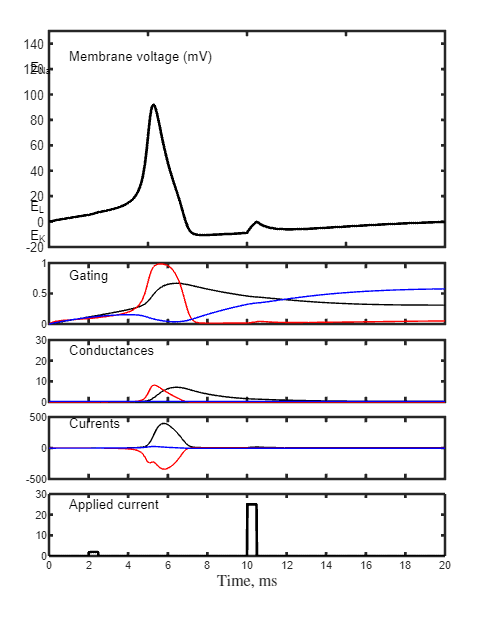

ans =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [300 40 600 750]
       Units: 'pixels'

  Show all properties


% for i=1:length(t)
%     if (t(i)>2 && t(i)<2.5)
%         I(i,1)=2;
%     elseif (t(i)>10 && t(i)<10.5)
%         I(i,1)=25;
%     else
%         I(i,1)=0;
%     end
% end
master_hh
plot_hh(dyn, pars)

Problem 4

pars.Vstar = 0;
% Finding the gating state values
pars.nstar = pars.alphan(pars.Vstar) / (pars.alphan(pars.Vstar) + pars.betan(pars.Vstar));
pars.mstar = pars.alpham(pars.Vstar) / (pars.alpham(pars.Vstar) + pars.betam(pars.Vstar));
pars.hstar = pars.alphah(pars.Vstar) / (pars.alphah(pars.Vstar) + pars.betah(pars.Vstar));

disp(pars.nstar)

    0.3177



disp(pars.mstar)

    0.0529



disp(pars.hstar)

    0.5961



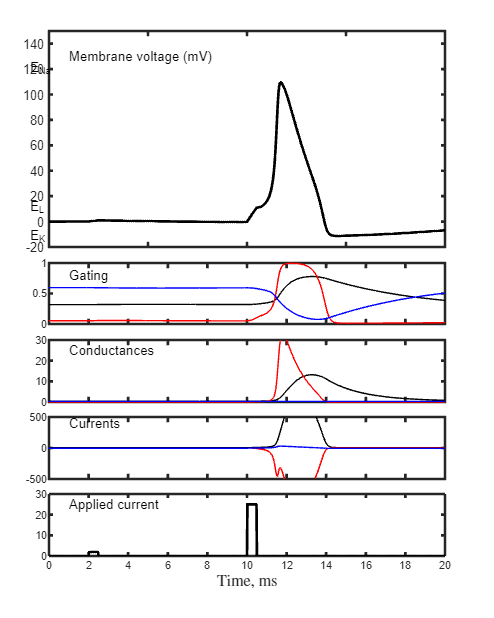

ans =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [300 40 600 750]
       Units: 'pixels'

  Show all properties



y0 = [pars.Vstar pars.nstar pars.mstar pars.hstar];
[t,y]=ode45(@model_hh,[0:0.02:20],y0,[],pars);

dyn1.t=t;
dyn1.V=y(:,1);
dyn1.n=y(:,2);
dyn1.m=y(:,3);
dyn1.h=y(:,4);
dyn1.gK=pars.gKbar*dyn1.n.^4;
dyn1.gNa=pars.gNabar*dyn1.m.^3.*dyn1.h;
dyn1.gL=pars.gL*ones(length(dyn1.t),1);
dyn1.IK=dyn1.gK.*(dyn1.V-pars.EK);
dyn1.INa=dyn1.gNa.*(dyn1.V-pars.ENa);
dyn1.IL=dyn1.gL.*(dyn1.V-pars.EL);
dyn1.appliedI = impulse_t(dyn1.t);

plot_hh(dyn1, pars)

Equilibrium voltage: 0 V

n*: .3177

m*: .0529

h*: .5961

Problem 4

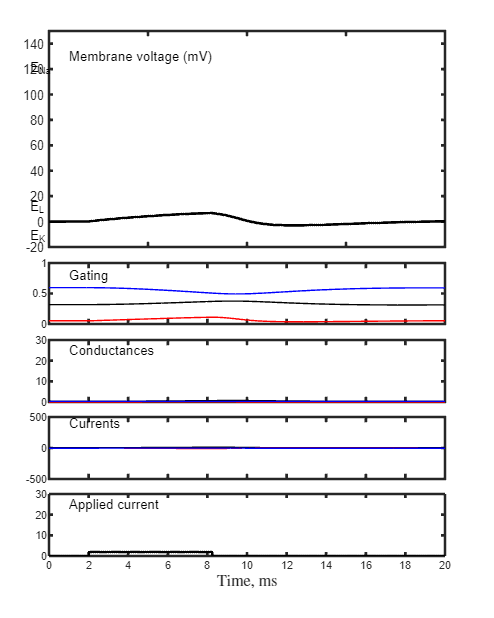

ans =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [300 40 600 750]
       Units: 'pixels'

  Show all properties


[t,y]=ode45(@model_hh1,[0:0.02:20],y0,[],pars);

dyn2.t=t;
dyn2.V=y(:,1);
dyn2.n=y(:,2);
dyn2.m=y(:,3);
dyn2.h=y(:,4);
dyn2.gK=pars.gKbar*dyn2.n.^4;
dyn2.gNa=pars.gNabar*dyn2.m.^3.*dyn2.h;
dyn2.gL=pars.gL*ones(length(dyn2.t),1);
dyn2.IK=dyn2.gK.*(dyn2.V-pars.EK);
dyn2.INa=dyn2.gNa.*(dyn2.V-pars.ENa);
dyn2.IL=dyn2.gL.*(dyn2.V-pars.EL);
dyn2.appliedI = impulse_t1(dyn2.t);

plot_hh(dyn2, pars)

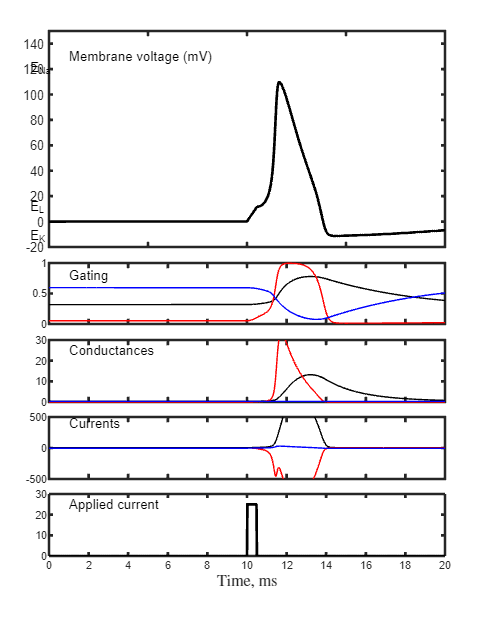

ans =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [300 40 600 750]
       Units: 'pixels'

  Show all properties



[t,y]=ode45(@model_hh2,[0:0.02:20],y0,[],pars);

dyn3.t=t;
dyn3.V=y(:,1);
dyn3.n=y(:,2);
dyn3.m=y(:,3);
dyn3.h=y(:,4);
dyn3.gK=pars.gKbar*dyn3.n.^4;
dyn3.gNa=pars.gNabar*dyn3.m.^3.*dyn3.h;
dyn3.gL=pars.gL*ones(length(dyn3.t),1);
dyn3.IK=dyn3.gK.*(dyn3.V-pars.EK);
dyn3.INa=dyn3.gNa.*(dyn3.V-pars.ENa);
dyn3.IL=dyn3.gL.*(dyn3.V-pars.EL);
dyn3.appliedI = impulse_t2(dyn3.t);

plot_hh(dyn3, pars)

In both plots, the product of current and time is equal to 12.5 A * ms. In the first plot, the time duration is 6.25 ms, and the applied current is 2 A. In the second plot, the time duration is .5 seconds, and the current is 25 A. However, the first plot does not generate a signal, while the second plot does. This shows that not all impulses are equal; a long but weak impulse will not generate a signal, but a short and strong one will.

Functions

function I1 = impulse_t1(t)
% function I = impulse_t(t)
%
% specifies the applied time-varying current
% works if t is a single value or many values
for i=1:length(t)
if (t(i)>2 && t(i)<8.25)
I1(i,1)=2;
else
I1(i,1)=0;
end
end
end

function I2 = impulse_t2(t)
% function I = impulse_t(t)
% 
% specifies the applied time-varying current
% works if t is a single value or many values
for i=1:length(t)
if (t(i)>10 && t(i)<10.5)
I2(i,1)=25;
else
I2(i,1)=0;
end
end
end

function dydt = model_hh1(t,y,pars)
% Joshua Weitz - BIOL 8814 - Neuron excitation - Fall 2018
%
% function dydt = model_hh(t,y,pars)
% This simulates the HH model using parameters embedded in pars
% and requires a separate function termed impluse_t which
% has information on the time-dependent applied current
% Variables
V=y(1);
n=y(2);
m=y(3);
h=y(4);
% Impulses
I=impulse_t1(t); % Specified in a function
% Dynamics
Vdot = (1/pars.C)*(I - pars.gKbar*(n^4)*(V-pars.EK) - pars.gNabar*(m^3)*h*(V-pars.ENa) - pars.gL*(V-pars.EL));
ndot = pars.alphan(V)*(1-n) - pars.betan(V)*n;
mdot = pars.alpham(V)*(1-m) - pars.betam(V)*m;
hdot = pars.alphah(V)*(1-h) - pars.betah(V)*h;
% Return the changes
dydt = [Vdot; ndot; mdot; hdot];
end

function dydt = model_hh2(t,y,pars)
% Joshua Weitz - BIOL 8814 - Neuron excitation - Fall 2018
%
% function dydt = model_hh(t,y,pars)
% This simulates the HH model using parameters embedded in pars
% and requires a separate function termed impluse_t which
% has information on the time-dependent applied current
% Variables
V=y(1);
n=y(2);
m=y(3);
h=y(4);
% Impulses
I=impulse_t2(t); % Specified in a function
% Dynamics
Vdot = (1/pars.C)*(I - pars.gKbar*(n^4)*(V-pars.EK) - pars.gNabar*(m^3)*h*(V-pars.ENa) - pars.gL*(V-pars.EL));
ndot = pars.alphan(V)*(1-n) - pars.betan(V)*n;
mdot = pars.alpham(V)*(1-m) - pars.betam(V)*m;
hdot = pars.alphah(V)*(1-h) - pars.betah(V)*h;
% Return the changes
dydt = [Vdot; ndot; mdot; hdot];
end